## Choose a Surface (run one cell in this section)

Note that all surfaces will have x, y, and z coordinates, but for 2D surfaces the z coordinate will be 0 everywhere. 

Prequisite

addpath(genpath('/projects/kg98/trangc/MBM'))


### 2D surface

#### Square

rng(1);
v = rand(1000,2)*20; v(:,3) = 0;
f = delaunay(v(:,1),v(:,2)); %#ok<*NASGU,*ASGLU>

#### Lshape

[v,f] = squareMesh3;
[v,f] = trimExcludedRois(v,f, ~(v(:,1)>10 & v(:,2)>10));

### 3D surface

#### Sphere

[v,f] = sphereMesh;

#### Torus

[v,f] = torusMesh;

**Fsaverage**

[v,f] = read_vtk(fullfile('/projects/kg98/trangc/MBM/data/demo_emp', 'fsaverage_164k_midthickness-lh.vtk')); % path to vtk file
    v = v';
    f = f';
    mask = readmatrix('/projects/kg98/trangc/MBM/data/demo_emp/fsaverage_164k_cortex-lh_mask.txt');
[v,f] = trimExcludedRois(v,f, mask);

**Fsaverage**

[v,f] = read_vtk(fullfile('/projects/kg98/trangc/MBM/data/demo_sim', 'fsLR_32k_midthickness-lh.vtk')); % path to vtk file
    v = v';
    f = f';

## Plot Appropriately (run one cell in this section)

### 2D surface (e.g. square, Lshape)

figure('Units', 'normalized', 'Position', [0 0 1 1]); nexttile; 
patch('Vertices', v, 'Faces', f, 'FaceColor', 'none', 'EdgeColor', 'black'); 
axis off equal tight; view(3);

% surface = struct('vertices', v, 'faces', f);
surface = calc_geometric_eigenmode(struct('vertices', v, 'faces', f)); 

for ii = 1:width(surface.evecs)
    nexttile;   
    patch('Vertices', surface.vertices+[0,0,50].*surface.evecs(:,ii), ...
        'Faces', surface.faces, 'FaceColor', 'interp', 'EdgeColor', 'none', ...
        'FaceVertexCData', surface.evecs(:,ii));     
    axis off equal tight; view(3); 
end

### 3D surface (e.g. sphere, torus)

figure('Units', 'normalized', 'Position', [0 0 1 1]); nexttile; 

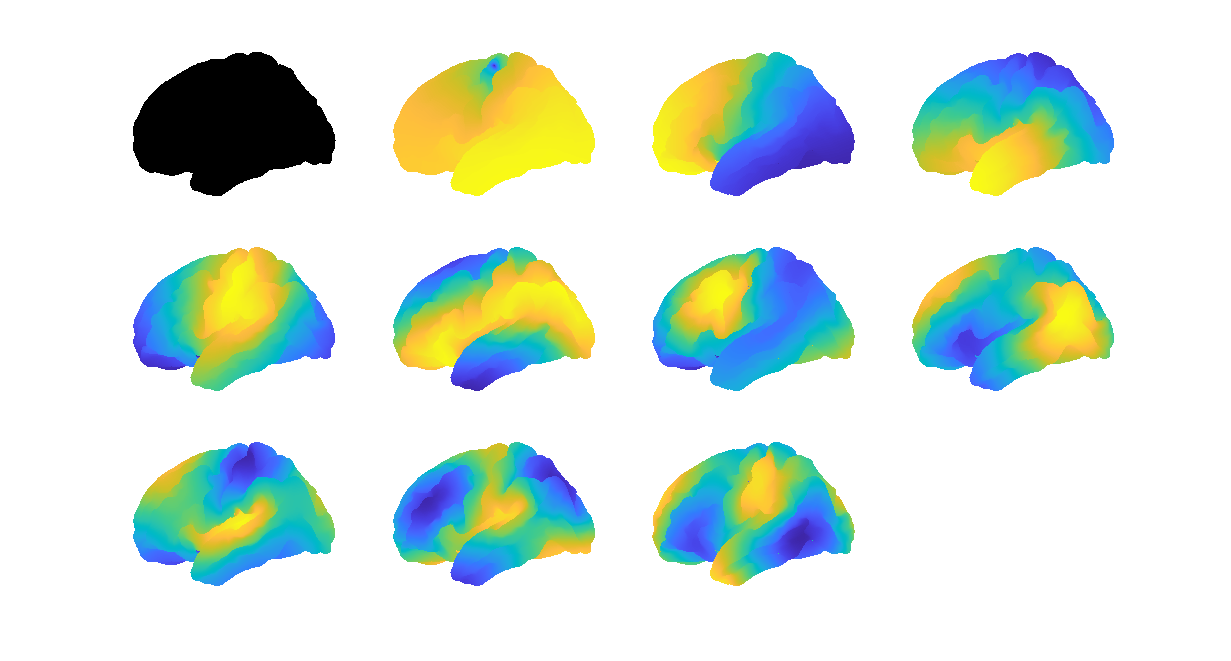

patch('Vertices', v, 'Faces', f, 'FaceColor', 'none', 'EdgeColor', 'black'); 
axis off equal tight; view(3);view([-90 0]);

surface = struct('vertices', v, 'faces', f);
surface = calc_geometric_eigenmode(surface); 

for ii = 1:width(surface.evecs)
    nexttile; 
    patch('Vertices', surface.vertices, 'Faces', surface.faces, ...
        'FaceColor', 'interp', 'EdgeColor', 'none', ...
        'FaceVertexCData', surface.evecs(:,ii)); 
    axis off equal tight; view(3);view([-90 0]);
end

### Example of reconstruction (3D)

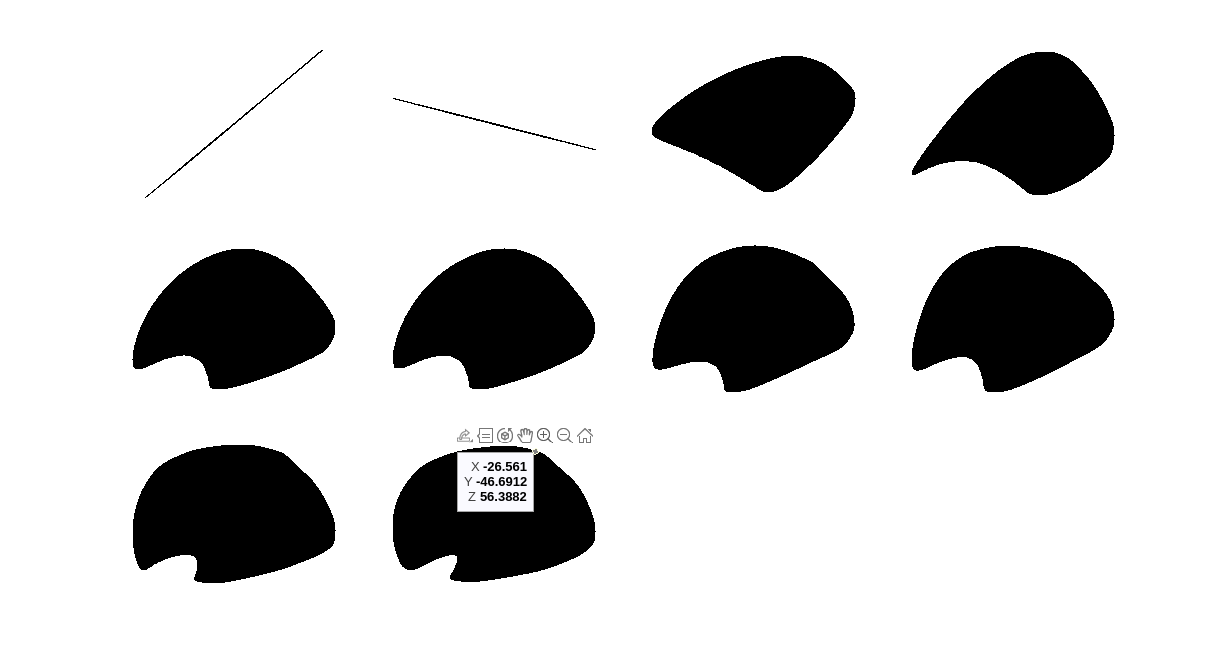

[~,v2] = calc_eigenreconstruction(v,surface,'orthogonal',1:10,surface); 
figure('Units', 'normalized', 'Position', [0 0 1 1]);
for i=1:10
     nexttile; 
patch('Vertices', squeeze(v2(:,i,:)), 'Faces', f, 'FaceColor', 'none', 'EdgeColor', 'black'); 
axis off equal tight; view(3);view([-90 0]);
end